# Magnetic Field of a Filament

This script demonstrates magnetic field of straight filament in vacuum.

#### Create Line

L = 10

L = 10

r = 1

r = 1

start = [0 0 -L];
stop = [0 0 L];
f = Filament(start, stop);

figure;
plot3(f);

#### Pick an Observation Point

obs = [r 0 0]

obs =      1     0     0


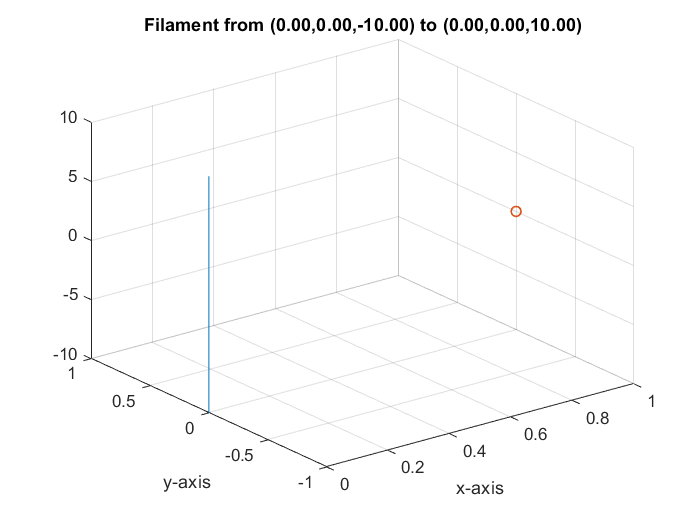


hold on;
scatter3(obs(1), obs(2), obs(3), 'LineWidth', 1);
axis 'auto xy';
hold off;

#### Calculate Magnetic Field Numerically

sample_count = 1000

sample_count = 1000


% Calculate magnetic field with specified sample count
numeric = f.observe(obs, sample_count);

#### Calculate Magnetic Field Theorically

theoretical = [0 constants.mu_zero*L/(2*pi*r*sqrt(L^2+r^2)) 0];

#### Report Error and Configuration

disp(f)

Filament(start=(0.00,0.00,-10.00) stop=(0.00,0.00,10.00))


fprintf("Magnetic field observed at (%0.2f,%0.2f,%0.2f):", obs(1), obs(2), obs(3));

Magnetic field observed at (1.00,0.00,0.00):

fprintf(" -> Numerically: (%E,%E,%E) T", numeric(1), numeric(2), numeric(3));

 -> Numerically: (0.000000E+00,1.990649E-07,0.000000E+00) T

fprintf(" -> Theoretically: (%E,%E,%E) T", ...
    theoretical(1), theoretical(2), theoretical(3));

 -> Theoretically: (0.000000E+00,1.990649E-07,0.000000E+00) T

n = abs(numeric);
t = abs(theoretical);
error = abs(numeric - theoretical) / theoretical * 100;
fprintf("Percentage error is %0.2f.", error);

Percentage error is 0.00.